# Solve DAE for a gantry crane

See the pendulum example in documentation:

- [https://www.mathworks.com/help/symbolic/solve-differential-algebraic-equations.html](https://www.mathworks.com/help/symbolic/solve-differential-algebraic-equations.html)

clear variables

results_dir = 'results';
if ~isfolder(results_dir)
    mkdir(results_dir)
end

The equations below were developed from cart-pole equations presented by:

- R. V. Florian, 2007, Correct equations for the dynamics of the cart-pole system.

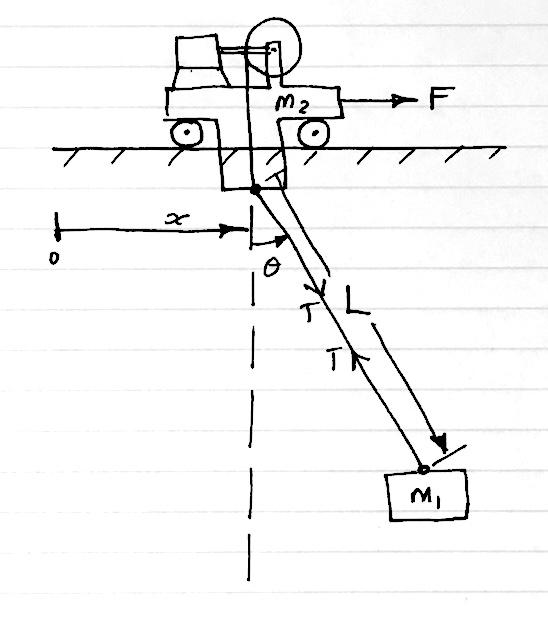

State variables

- Horizontal position of cart (from left) $x\left(t\right)$

- Horizontal velocity of cart $\dot{x} \left(t\right)$

- Angle of cable (anti-clockwise from vertical down position) $\theta \left(t\right)$

- Angular velocity of cable $\dot{\;\theta \;} \left(t\right)$

- Cable length $L\left(t\right)$

Other variables

- Downwards force on track from cart $N_c \left(t\right)$

- Frictional force exerted on cart by track $F_F \left(t\right)$

- Force exerted on cart by cable (and on load) $T\left(t\right)$

Potential input variables

- Horizontal driving force on cart $F\left(t\right)$

- Speed of cable leaving winch $\dot{L} \left(t\right)$

Parameters

- Cart mass $m_c$

- Load mass $m_p$

- Acceleration due to gravity $g$

- Coefficient of friction for cart and track $\mu_c$

- Radius of the load, $r$

- Drag coefficient of load $c_d$

- Mass density of air $\rho_a$

System of DAEs


$$\begin{array}{l}
N_c =\left(m_c +m_p \right)g-m_p l\left(\ddot{\theta} \;\sin \theta +{\dot{\theta} }^2 \;\cos \theta \right)\\
\ddot{\theta} =\frac{g\;\sin \theta +\cos \theta \left\lbrace \frac{-F-m_p l{\dot{\theta} }^2 \left(\sin \theta +\mu_c \;\textrm{sgn}\left(N_c \dot{x} \right)\cos \theta \right)}{m_c +m_p }+\mu_c g\;\textrm{sgn}\left(N_c \dot{x} \right)\right\rbrace -\frac{{\pi^{3\;} c_d L^2 r}^2 }{2m_p }{\dot{\theta} }^2 }{l\left\lbrace \frac{4}{3}-\frac{m_p \cos \theta }{m_c +m_p }\left(\cos \theta -\mu_c \;\textrm{sgn}\left(N_c \dot{x} \right)\right)\right\rbrace }\\
\ddot{x} =\frac{F+m_p l\left({\dot{\theta} }^2 \;\sin \theta -\ddot{\theta} \;\cos \theta \right)-\mu_c N_c \textrm{sgn}\left(N_c \dot{x} \right)}{m_c +m_p }
\end{array}$$


## First, define an autonomous system

i.e. `F(t) = 0`, `L(t) = l` (constant)

% Define symbolic variables
syms x(t) theta(t) Nc(t) F mc mp L g muc r cd rho

eqn1 = 1000 * Nc == ...
    (mc + mp) * g - mp * L * (diff(theta(t), 2) * sin(theta(t)) + diff(theta(t))^2 * cos(theta(t)))

$$eqn1(t) = 1000\,\mathrm{Nc}\left(t\right)=g\,\left(\mathrm{mc}+\mathrm{mp}\right)-L\,\mathrm{mp}\,\left(\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)$$

eqn2 = diff(theta(t), 2) == ...
    (g * sin(theta(t)) + cos(theta(t)) * ( ...
        (-F - mp * L * diff(theta(t))^2 * (sin(theta(t)) + muc * sign(Nc) * sign(diff(x(t))) * cos(theta(t))) ...
     ) / (mc + mp) + muc * g * sign(Nc) * sign(diff(x(t)))) - pi^3 * rho * cd * (L * r * diff(theta(t)))^2 / (2 * mp) ) ...
    / (L * (4/3 - mp * cos(theta(t)) / (mc + mp) * (cos(theta(t)) - muc * sign(Nc) * sign(diff(x(t))))))

$$eqn2(t) = \begin{array}{l} \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{\cos\left(\theta \left(t\right)\right)\,\left(\frac{F+L\,\mathrm{mp}\,\left(\sin\left(\theta \left(t\right)\right)+\mathrm{muc}\,\mathrm{sign}\left(\mathrm{Nc}\left(t\right)\right)\,\sigma_{1}\,\cos\left(\theta \left(t\right)\right)\right)\,\sigma_{2}}{\mathrm{mc}+\mathrm{mp}}-g\,\mathrm{muc}\,\mathrm{sign}\left(\mathrm{Nc}\left(t\right)\right)\,\sigma_{1}\right)-g\,\sin\left(\theta \left(t\right)\right)+\frac{15.5031\,L^{2}\,\mathrm{cd}\,r^{2}\,\rho \,\sigma_{2}}{\mathrm{mp}}}{L\,\left(\frac{\mathrm{mp}\,\cos\left(\theta \left(t\right)\right)\,\left(\cos\left(\theta \left(t\right)\right)-\mathrm{muc}\,\mathrm{sign}\left(\mathrm{Nc}\left(t\right)\right)\,\sigma_{1}\right)}{\mathrm{mc}+\mathrm{mp}}-1.3333\right)}\\ \mathrm{where}\\ \sigma_{1}=\mathrm{sign}\left(\frac{\partial }{\partial t}x\left(t\right)\right)\\ \sigma_{2}={\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2} \end{array}$$

eqn3 = diff(x(t), 2) == ...
    (F + mp * L * (diff(theta(t))^2 * sin(theta(t)) - diff(theta(t), 2) * cos(theta(t))) ...
     - muc * 1000 * Nc * sign(Nc) * sign(diff(x(t)))) ...
    / (mc + mp)

$$eqn3(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\frac{F+L\,\mathrm{mp}\,\left(\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\right)-1000\,\mathrm{muc}\,\mathrm{sign}\left(\mathrm{Nc}\left(t\right)\right)\,\mathrm{sign}\left(\frac{\partial }{\partial t}x\left(t\right)\right)\,\mathrm{Nc}\left(t\right)}{\mathrm{mc}+\mathrm{mp}}$$

eqns = [eqn1 eqn2 eqn3];
vars = [x(t); theta(t); Nc(t)];
origVars = length(vars)

origVars = 3

Check Incidence of Variables

M = incidenceMatrix(eqns, vars)

M =      0     1     1
     1     1     1
     1     1     1


Reduce Differential Order

[eqns, vars] = reduceDifferentialOrder(eqns, vars)

$$eqns = \left(\begin{array}{c} 1000\,\mathrm{Nc}\left(t\right)-g\,\left(\mathrm{mc}+\mathrm{mp}\right)+L\,\mathrm{mp}\,\left(\sin\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{Dthetat}\left(t\right)+\cos\left(\theta \left(t\right)\right)\,{\mathrm{Dthetat}\left(t\right)}^{2}\right)\\ \frac{\partial }{\partial t}\mathrm{Dthetat}\left(t\right)-\frac{\cos\left(\theta \left(t\right)\right)\,\left(\frac{L\,\mathrm{mp}\,\left(\sin\left(\theta \left(t\right)\right)+\mathrm{muc}\,\mathrm{sign}\left(\mathrm{Dxt}\left(t\right)\right)\,\mathrm{sign}\left(\mathrm{Nc}\left(t\right)\right)\,\cos\left(\theta \left(t\right)\right)\right)\,{\mathrm{Dthetat}\left(t\right)}^{2}+F}{\mathrm{mc}+\mathrm{mp}}-g\,\mathrm{muc}\,\mathrm{sign}\left(\mathrm{Dxt}\left(t\right)\right)\,\mathrm{sign}\left(\mathrm{Nc}\left(t\right)\right)\right)-g\,\sin\left(\theta \left(t\right)\right)+\frac{15.5031\,L^{2}\,\mathrm{cd}\,r^{2}\,\rho \,{\mathrm{Dthetat}\left(t\right)}^{2}}{\mathrm{mp}}}{L\,\left(\frac{\mathrm{mp}\,\cos\left(\theta \left(t\right)\right)\,\left(\cos\left(\theta \left(t\right)\right)-\mathrm{muc}\,\mathrm{sign}\left(\mathrm{Dxt}\left(t\right)\right)\,\mathrm{sign}\left(\mathrm{Nc}\left(t\right)\right)\right)}{\mathrm{mc}+\mathrm{mp}}-1.3333\right)}\\ \frac{L\,\mathrm{mp}\,\left(\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}\mathrm{Dthetat}\left(t\right)-\sin\left(\theta \left(t\right)\right)\,{\mathrm{Dthetat}\left(t\right)}^{2}\right)-F+1000\,\mathrm{muc}\,\mathrm{sign}\left(\mathrm{Dxt}\left(t\right)\right)\,\mathrm{sign}\left(\mathrm{Nc}\left(t\right)\right)\,\mathrm{Nc}\left(t\right)}{\mathrm{mc}+\mathrm{mp}}+\frac{\partial }{\partial t}\mathrm{Dxt}\left(t\right)\\ \mathrm{Dxt}\left(t\right)-\frac{\partial }{\partial t}x\left(t\right)\\ \mathrm{Dthetat}\left(t\right)-\frac{\partial }{\partial t}\theta \left(t\right) \end{array}\right)$$

$$vars = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ \mathrm{Nc}\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right) \end{array}\right)$$

Check Differential Index of System

if ~isLowIndexDAE(eqns, vars)
    disp("Reducing Differential Index...")
    % Reduce Differential Index with reduceDAEIndex
    [DAEs, DAEvars] = reduceDAEIndex(eqns, vars)
    % Eliminate redundant equations and variables
    [DAEs, DAEvars] = reduceRedundancies(DAEs, DAEvars)
    % Check the differential index of the new system
    assert(isLowIndexDAE(DAEs, DAEvars))
else
    DAEs = eqns;
    DAEvars = vars;
end

### Convert DAE system to MATLAB function

pDAEs = symvar(DAEs);
pDAEvars = symvar(DAEvars);
extraParams = setdiff(pDAEs, pDAEvars)

$$extraParams = \left(\begin{array}{ccccccccc} F & L & \mathrm{cd} & g & \mathrm{mc} & \mathrm{mp} & \mathrm{muc} & r & \rho \end{array}\right)$$

Create the function handle. 

%f = daeFunction(DAEs, DAEvars, F, L, cd, g, mc, mp, muc, r, rho);

To save the DAE equations as a function script use this option

filename = 'craneDAEFunction.m';
f = daeFunction(DAEs, DAEvars, F, L, cd, g, mc, mp, muc, r, rho, 'File', filename);

### Set parameter values

F = 0;
L = 3;
cd = 0.47;  % drag coefficient of a sphere = 0.47
g = 10;
mc = 5;
mp = 2;
muc = 0.2;
r = 0.25;  % radius of load
rho = 1.293;  % density of air = 1.293

% Parameter values as struct
params = struct();
params.F = F;
params.L = L;
params.cd = cd;
params.g = g;
params.l = L;
params.mc = mc;
params.mp = mp;
params.muc = muc;
params.r = r;
params.rho = rho;

Create function for ode15i

F_DAE = @(t, Y, YP) f(t, Y, YP, F, L, cd, g, mc, mp, muc, r, rho);

### Find initial condition

DAEvars

$$DAEvars = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ \mathrm{Nc}\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right) \end{array}\right)$$

Note that `Dxt(t)`, `Dthetat(t)`, ... etc. are the first derivatives of `x(t)` ... etc.

Provide an estimate of the initial condition

% Variables
% 1 degrees = 0.0172
y0est = [0; deg2rad(30); 0; 0; 0];
% Their derivatives
yp0est = [0; 0; 0; 0; 0];

Set tolerances and do numerical search.

opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
FIXED_Y0 = [1 1 0 1 1]';
FIXED_YP0 = [0 0 0 0 0]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, FIXED_YP0, opt)

y0 =          0
    0.5236
    0.0655
         0
         0


yp0 =          0
         0
         0
   -1.1056
    1.4894


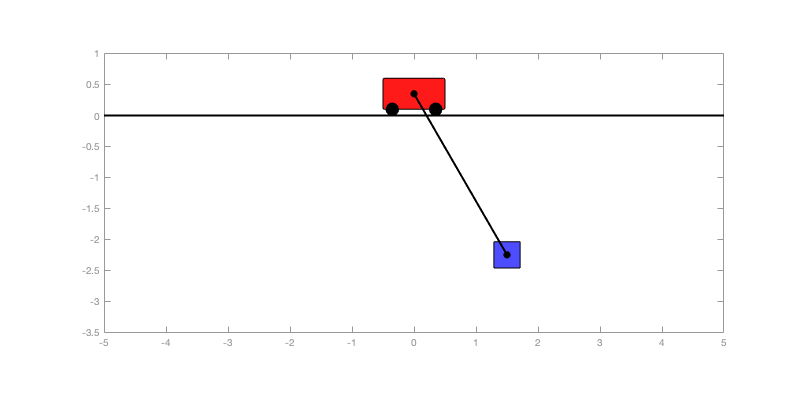

figure(1); clf
draw_crane(y0([1 3 2 4]),params)

### Solve DAEs Using ode15i

[tSol, ySol] = ode15i(F_DAE, [0 2], y0, yp0, opt);

Plot solution

figure(2); clf
plot(tSol, ySol(:, 1:origVars), 'LineWidth', 2)
xlabel("Time ($t$)", 'Interpreter', 'latex')
labels = arrayfun(@(i) char(DAEvars(i)), 1:origVars, 'UniformOutput', false);
legend(labels, 'Location', 'Best', 'Interpreter', 'latex')
grid on

### Save results to file

labels = arrayfun(@(i) char(DAEvars(i)), 1:numel(DAEvars), 'UniformOutput', false);
sim_results = array2table([tSol ySol], 'VariableNames', [{'t'} labels]);
filename = "crane_benchmark_sim.csv";
writetable(sim_results, fullfile(results_dir, filename))

### Solve using function script file

Solve the equations using the function script created by `daeFunction` above and check results are identical.

% Solve DAEs
F_DAE2 = @(t, Y, YP) craneDAEFunction(t, Y, YP, F, L, cd, g, mc, mp, muc, r, rho);
[tSol, ySol] = ode15i(F_DAE2, [0 1], y0, yp0, opt);

Solve using the edited function in crane_DAEs.m

% Solve DAEs
F_DAE2 = @(t, Y, YP) crane_DAEs(t, Y, YP, params);
[tSol2, ySol2] = ode15i(F_DAE2, [0 1], y0, yp0, opt);
assert(isequal(tSol, tSol2))
assert(max(ySol - ySol2, [], [1 2]) < 1e-14)